# **IO3xx SPI - Loopback Master Sync**

This example demonstrates the SPI code module functionalities using two **SPI** blocks***,*** which are both on the same I/O module connected to a loopback. One of the SPI blocks is set to master mode and the other block is set to slave mode. You can test the basic functionality of the SPI code module by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports at least **2 x SPI channels**

- A connector cable from the I/O module to the terminal board

- A terminal board with jumper wires

### Test Setup

In this example, data is sent from the SPI master to the SPI slave and vice versa. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, look for the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. 

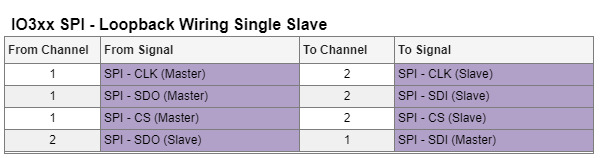

## Initialize and Open the Simulink Model

% Open Simulink model
modelName = 'sgMdl_IO3xx_SPI_Loopback_MasterSync';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

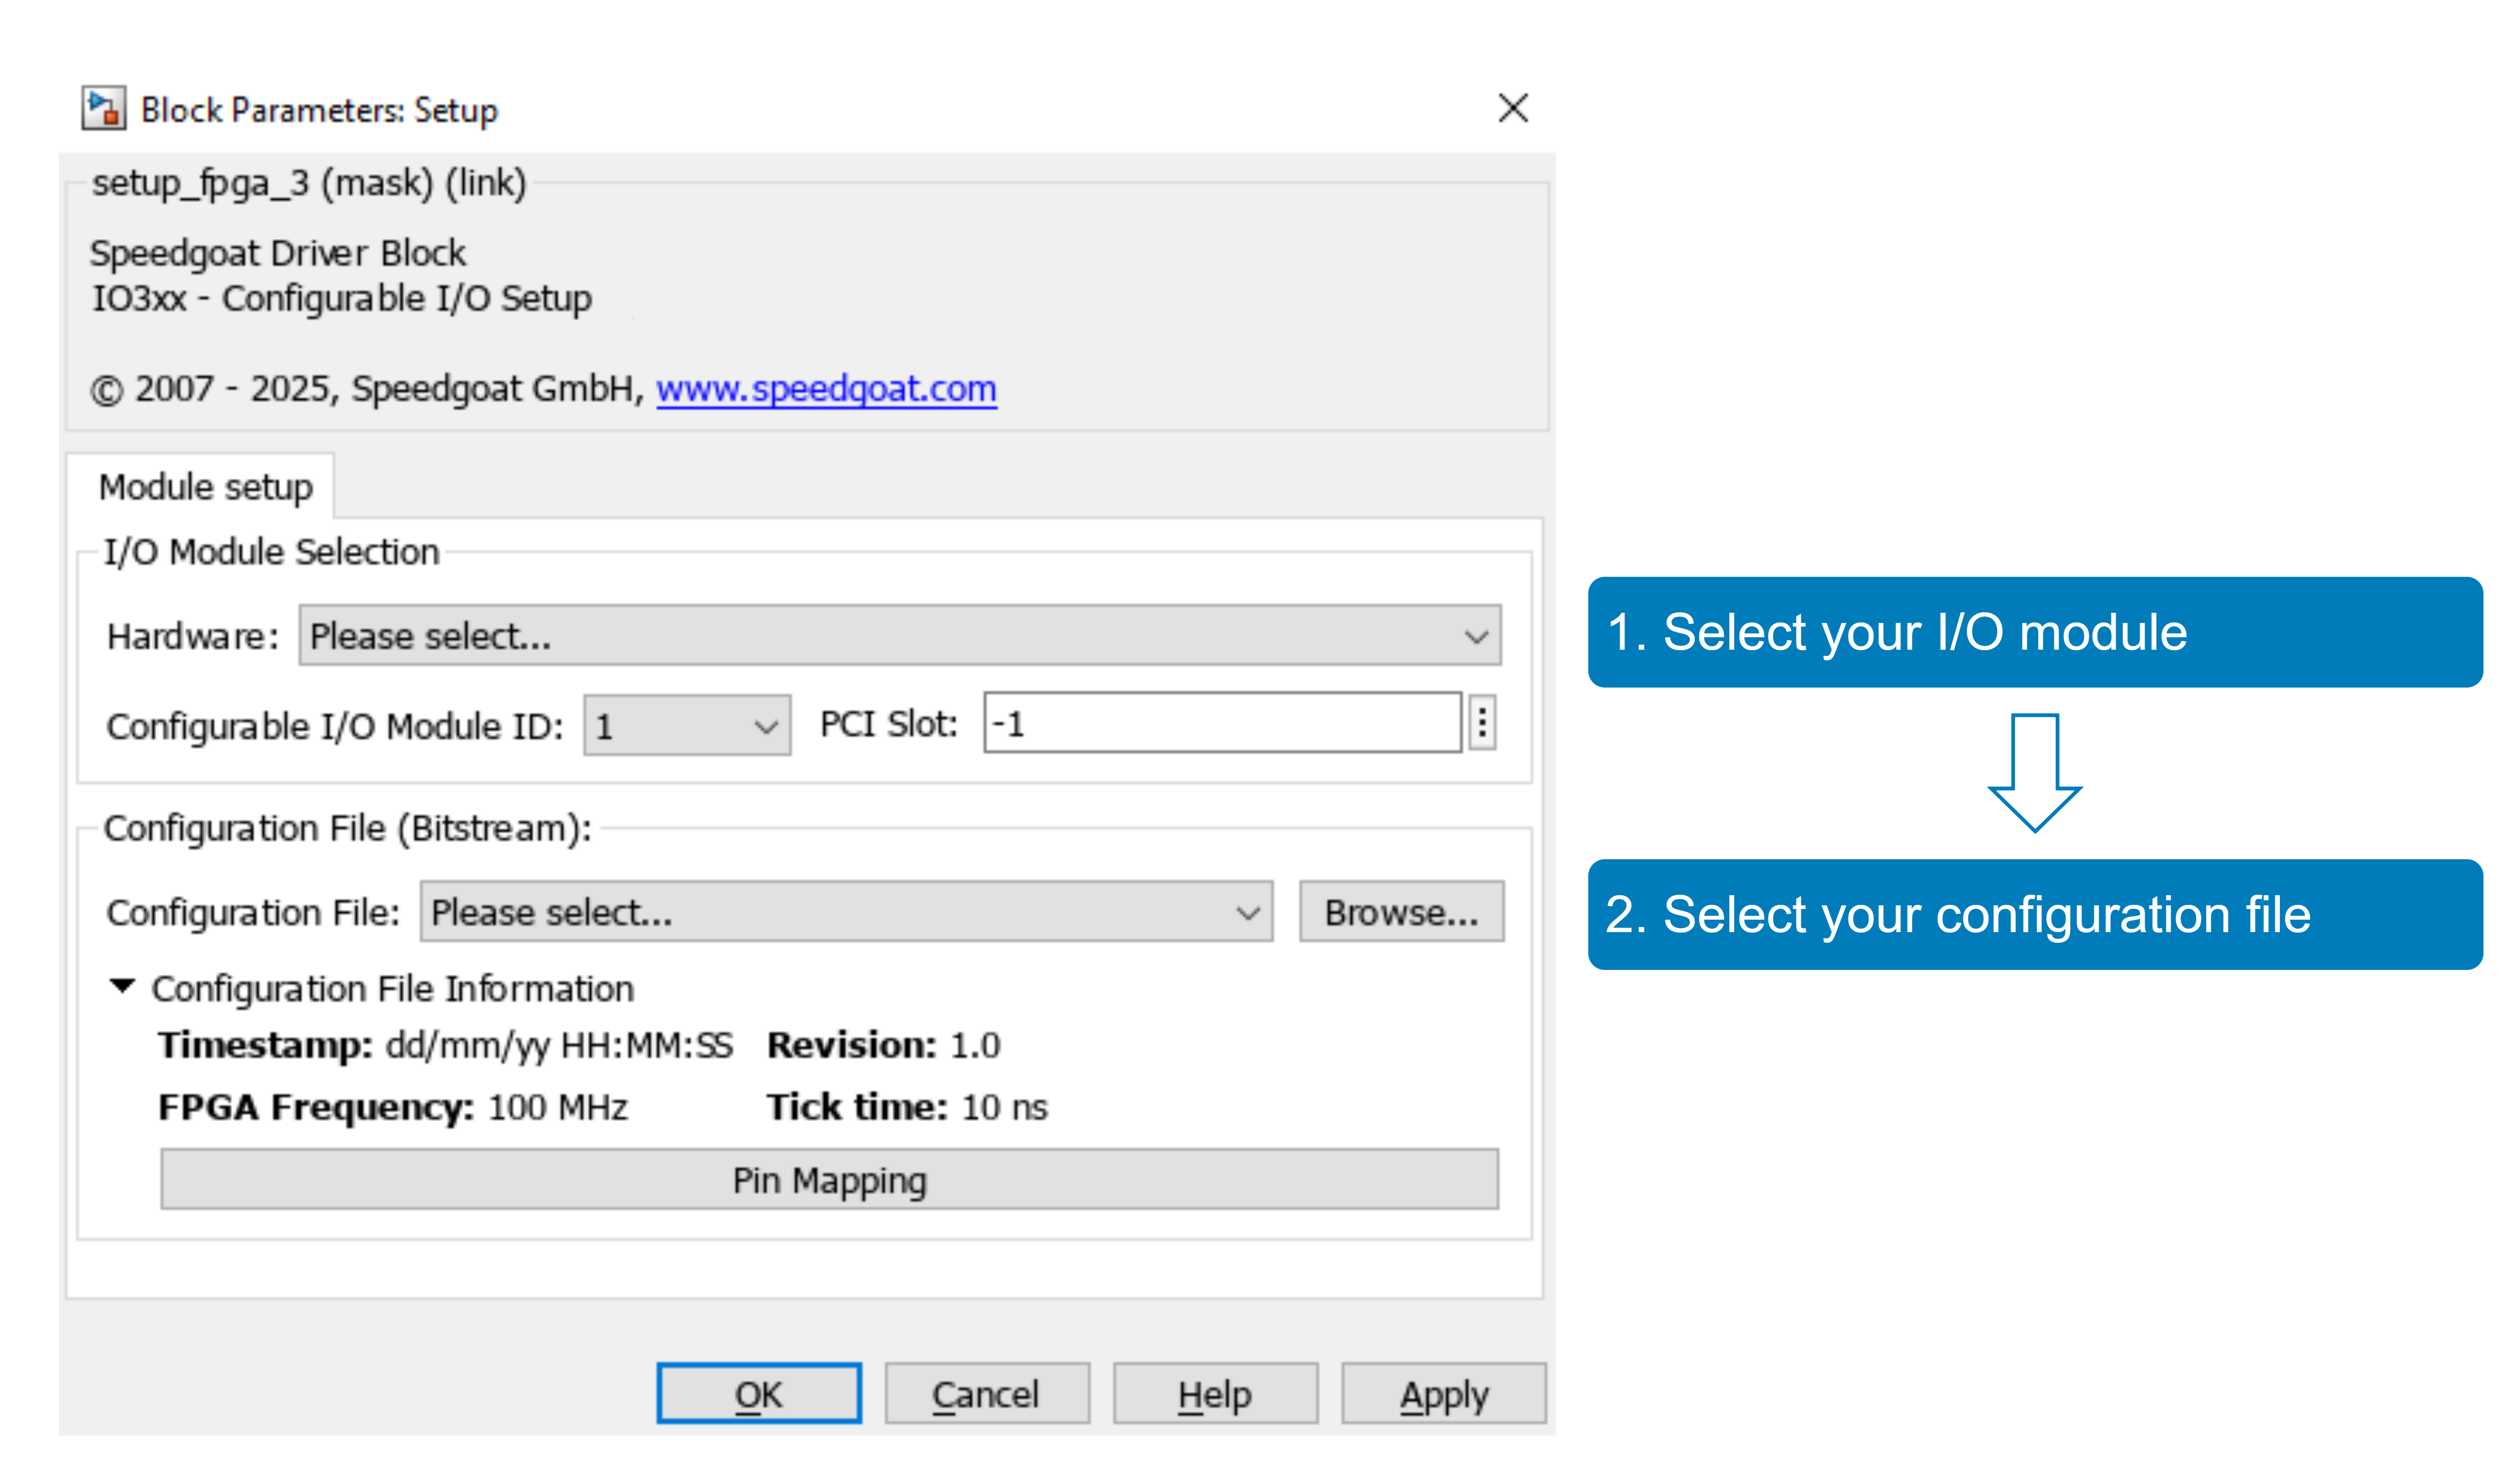

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### SPI Master

In the model on the block **SPI Master**, the parameter **Role** is set to **Master**. That means that this SPI unit defines the details of the SPI data transfer:

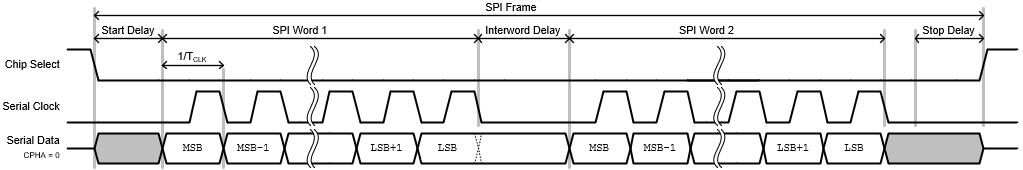

The following parameters are available in master mode to define the SPI frame:

- **CPOL** and **CPHA** define clock phase and clock polarity (both set 0 in this example)

- **Transmission Frequency** can be used to set the desired baud rate. Note that not all baud rates can be exactly met since the time resolution is limited to the FPGA Frequency of the used IO3xx Module. Next to this parameter, the **Effective Frequency** informs about the real value that is applied (as close as possible to the desired value)

- **Start Delay** defines the delay at the SPI frame start (Chip select activation until frame start)

- **Interword Delay** defines the delay within the different words being transferred

- **Stop Delay** defines the delay that is additionally added after the last word has been transferred until Chip Select is deactivated again

- **Delay Compensation** can be used to compensate a delay between SPI master clock and slave serial data, which occurs due to physical signal transfer delays

- **Words per Frame** defines the number of words being transferred within a single SPI transfer

- **Bits per Word** defines the number of bits being transferred within a single data word

- **Transmit LSbit first** defines if each word shall be transferred with the LSB first

### SPI Slave

In the model on the block **SPI Slave**, the parameter **Role** is set to **Slave**.

Following parameters are available in slave mode to define the SPI frame:

- **CPOL** and **CPHA** define clock phase and clock polarity (both set 0 in this example)

- **Words per Frame** defines the number of words being transferred within a single SPI transfer

- **Bits per Word** defines the number of bits being transferred within a single data word

- **Transmit LSbit first** defines if each word shall be transferred with the LSB first

### Model Behavior

The **SPI master** block defines the SPI frame. The **Words per Frame** is set to 16 and the **Bits per Word** is set to 12. With the **Transmission Frequency** set to 333 kHz, **Start Delay** set to 100 ns, **Interword Delay** set to 1 μs and **Stop Delay** set to 1 μs, the total Frame length is almost 785 μs. This time is also displayed on the mask of the **SPI Master** block.

In the **SPI Master** block, the parameter **Sync Mode** is activated. This means that at each model sample step (which is 1 ms on the example model), the SPI Master initiates a new SPI frame transmission. In this case, the underlying driver of the **SPI Master** block actively waits until the SPI frame is finished. Therefore, it is crucial that the total length of the SPI frame is smaller than the model sample step time.

Note that the **Words per Frame** of the SPI master is set to 16, but the **Words per Frame** of the SPI slave is only set to 8. In this case, the slave only receives the first 8 data words from the master and only sends 8 data words Tx data back to the master, the last 8 data words are transmitted as 0.

#### Transferred Data from Master to Slave

The Tx data from the **SPI Master** block is based on a free-running counter (incremented with each model step or SPI frame). The value of this counter is sent with Tx word 1 of the **SPI Master **block, and the following Tx words 2 to 16 add additional offsets to this counter value (Tx word 2 offset is dec200, Tx word 3 offset is dec400, ...).

#### Transferred Data from Slave to Master

The Tx data from the **SPI Slave** block is based on a free-running counter (incremented with each model step or SPI frame). The value of this counter is sent with Tx word 1 of the **SPI Slave **block, the following Tx words 2 to 8 add additional offsets to this counter value (Tx word 2 offset is dec100, Tx word 3 offset is dec200, etc.).

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);
% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  
% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

## Check the Results

To check if the loopback is working as expected, open the Simulink scope that is connected to the following signals:

- RxDataMaster: The received data on the SPI Master are displayed here. They should be equal to the SPI Slave Tx data.

- RxDataSlave: The received data on the SPI Slave are displayed here. They should be equal to the SPI Master Tx data.

- RxDataSlaveValid: This signal indicates if the above RxDataSlave are valid.

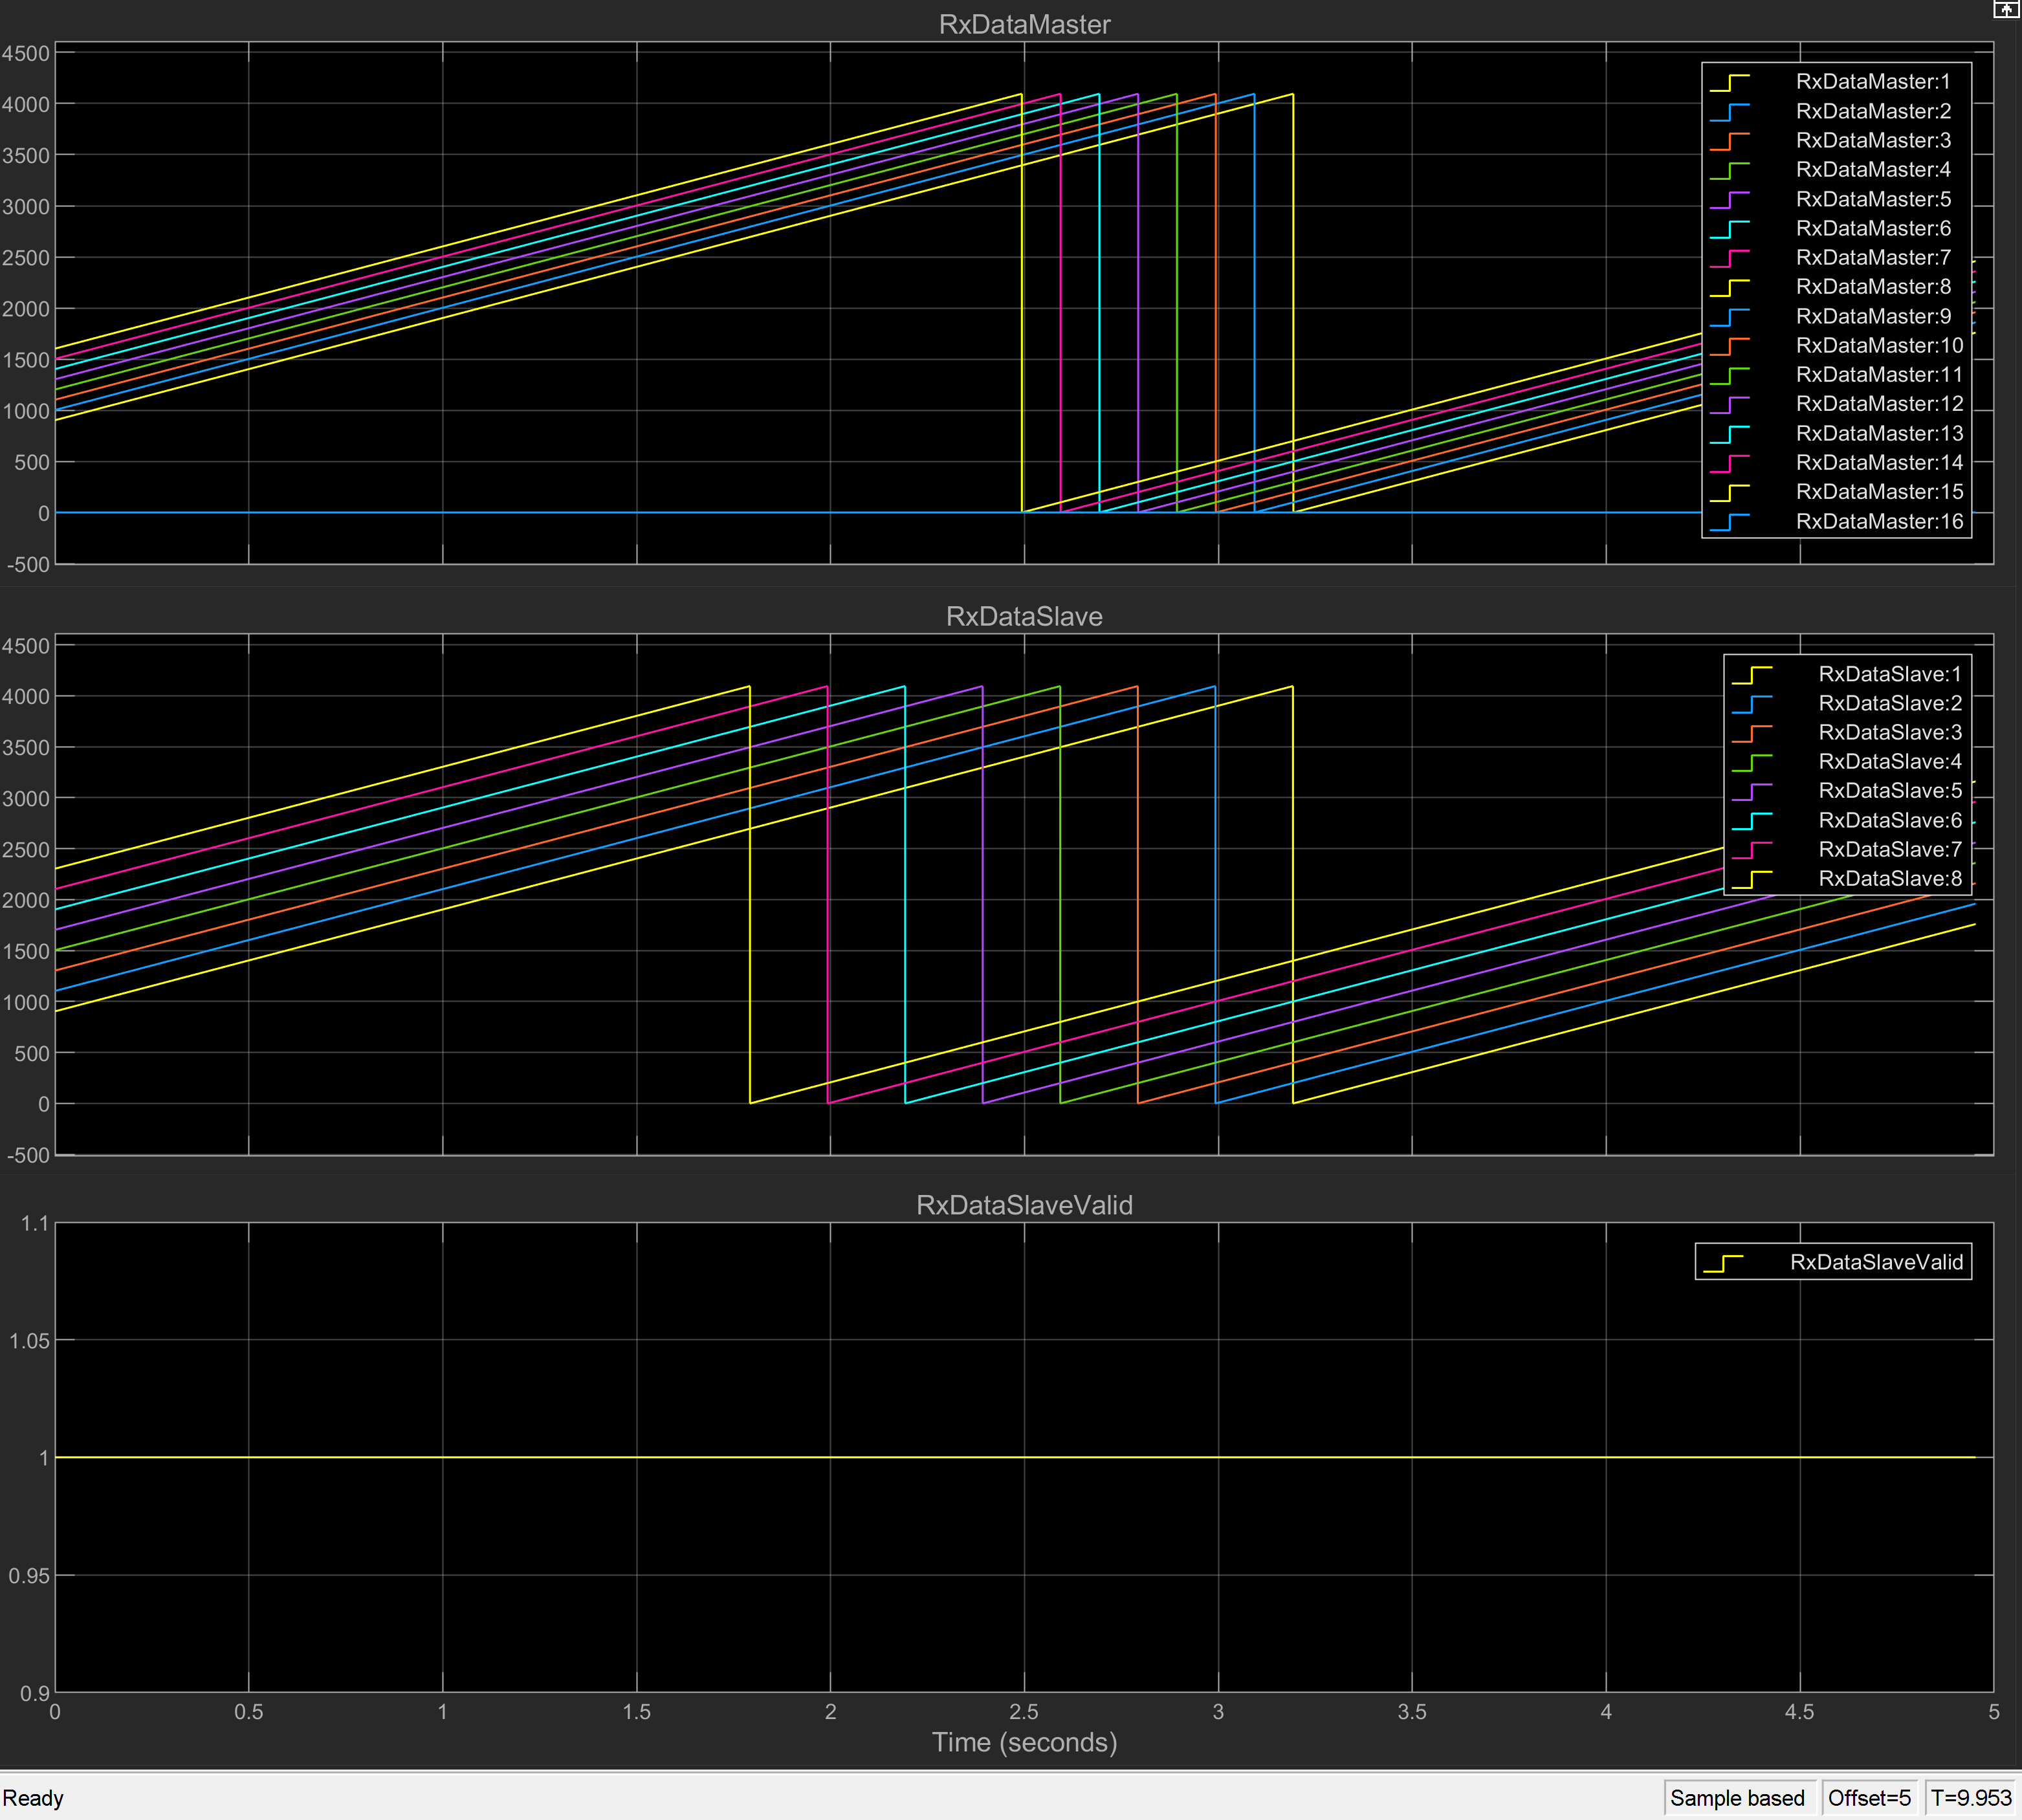

The data is based on a free-running counter that overflows after $2^{12\;} =4096$ steps due to the SPI word length being set to 12 bits. Since the model sample time is set to 1 ms, this overflow happens every 4.096 seconds.

### RxDataMaster

The RxDataMaster is expected to be the Tx Data of the SPI Slave.

The Tx data 1 of the SPI Slave block has a 0-offset. This signal is received as Rx Data on the master (RxDataMaster:1 in the scope).

Due to the **Words per Frame** on Slave SPI is only 8, RxDataMaster 9:16 are all 0. 

### RxDataSlave

The RxDataSlave is expected to be the Tx Data of the SPI Master.

The Tx data 1 of the SPI Master block has a 0-offset. This signal is received as Rx Data on the slave (RxDataSlave:1 in the scope).

Due to the **Words per Frame** on Slave SPI is only 8, we can only observe RxDataSlave 1:8. **Words per Frame** on Master SPI is set to 16, however the slave only receives the first 8 data words.

## Additional References

The following links describe the SPI and all its parameters in details:

- [SPI v2 Driver Block](https://www.speedgoat.com/help/slrt/page/io_main/refentry_spi_masterslave_v2)

- [SPI Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_spi_usage_notes)